# **Generación de Números Aleatorios**

`Autor: Dr. Abdelmalik Moujahid`

## `Método de Rechazo`

El método de rechazo, también conocido como **método de aceptación-rechazo**, es una técnica utilizada para generar variables aleatorias con una distribución específica mediante la aceptación de ciertos valores y el rechazo de otros. Este método es particularmente útil cuando no es fácil o posible generar directamente variables aleatorias según la distribución deseada.

A continuación, se describe el método de rechazo en términos generales:

A continuación, se describe el método de rechazo en términos generales:

- **Generación de una variable auxiliar**: Selecciona una variable aleatoria $X$de una distribución fácil de generar, generalmente una distribución de probabilidad continua que envuelve o es mayor que la distribución objetivo, $g_X \left(x\right)$.

- **Generación de una variable de aceptación/rechazo**: Selecciona una variable aleatoria $U$ de una distribución uniforme en el intervalo $\left\lbrack 0,1\right\rbrack$.

- **Prueba de aceptación/rechazo:** **Calcula la función de densidad de probabilidad (PDF)** de la variable auxiliar en el punto $X$ y compárala con $U$. Si *U* es menor o igual a la PDF en *X*, acepta *X* como una muestra de la distribución objetivo; de lo contrario, rechaza *X* y repite el proceso.

## Ejemplo 1: 

Supongamos que queremos generar variables aleatorias con una **distribución exponencial** $f_X \left(x\right)=\lambda \;e^{-\lambda \;x}$ usando una **envolvente uniforme**.

**Funciones de densidad de probabilidad:**

- PDF de la distribución exponencial: $f_X \left(x\right)=\lambda \;e^{-\lambda \;x}$  para $x\ge 0$.

- PDF de la envolvente uniforme: $f_U \left(u\right)=\frac{1}{\left(b-a\right)}$ para $a\le u\le b$, donde *a* y *b* son los extremos del intervalo de la envolvente uniforme.

**Método de rechazo:**

- Generamos una variable aleatoria $X$ con **distribución uniforme** en el intervalo $\left\lbrack a,b\right\rbrack$.

- Aceptamos la muestra $X$ con probabilidad $p=\frac{f_X \left(X\right)}{{M\;f}_U \left(u\right)}$�, donde $M$ es una constante que asegura que $f_X \left(x\right)\le M$ para todo $x$ y $u$.

**Implementación:**

- Repetimos los pasos anteriores hasta obtener el número deseado de muestras, aceptando aquellas que cumplen la condición de aceptación.

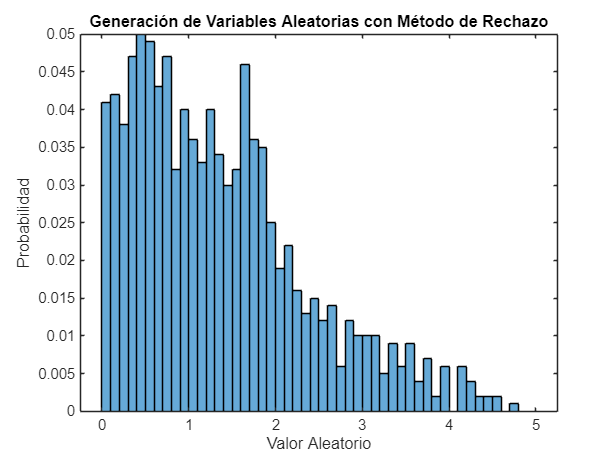

% Parámetro de la distribución exponencial
lambda = 1;
% Función de densidad de probabilidad de la distribución exponencial
pdf_exponencial = @(x) lambda * exp(-lambda * x);

% Función de densidad de probabilidad de la envolvente uniforme
a_uniforme = 0;
b_uniforme = 5; % Suponemos una envolvente uniforme en [0, 5]
pdf_uniforme = 1 / (b_uniforme - a_uniforme);

% Número de muestras a generar
num_samples = 1000;

% Generación de variables aleatorias mediante el método de rechazo
samples = zeros(1, num_samples);
accepted_samples = 0;

while accepted_samples < num_samples
    % Generar una muestra de la envolvente uniforme
    x = a_uniforme + (b_uniforme - a_uniforme) * rand();    
    % Generar una muestra de la distribución exponencial
    u = rand();
    if u <= pdf_exponencial(x) / pdf_uniforme
        % Aceptar la muestra
        accepted_samples = accepted_samples + 1;
        samples(accepted_samples) = x;
    end
end

% Visualizar los resultados
histogram(samples, 'Normalization', 'probability', 'BinEdges', 0:0.1:b_uniforme);
title('Generación de Variables Aleatorias con Método de Rechazo');
xlabel('Valor Aleatorio');
ylabel('Probabilidad');

## Ejemplo 2: 

Supongamos que queremos generar variables aleatorias con una **distribución dada** $f_X \left(x\right)$ usando una **envolvente uniforme**.

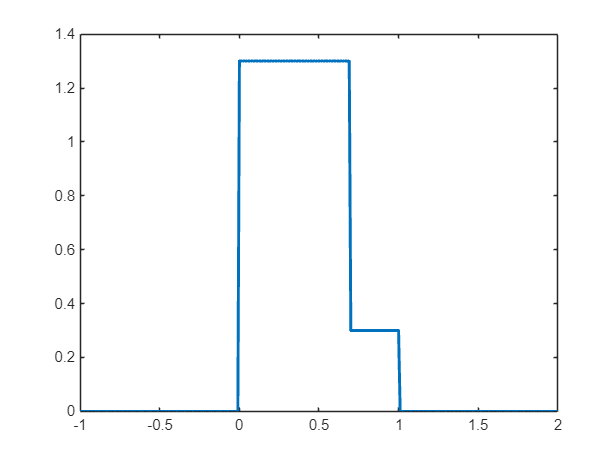

close all
clear all

%función de densidad original
a = 0;
b = 0.7;
c = 1;

% Función de densidad de probabilidad de la distribución
pdf_1 = @(x) 1.3*(x>=0 & x<0.7)+0.3*(x>=0.7&x<=1);

x=-1:.01:2;
figure(1)
plot(x,pdf_1(x),'LineWidth',2)

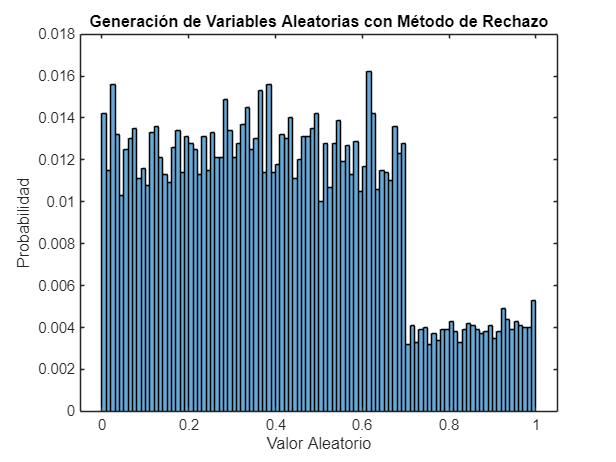

% Función de densidad de probabilidad de la distribución
pdf_1 = @(x) 1.3*(x>=0 & x<0.7)+0.3*(x>=0.7&x<=1);

% Función de densidad de probabilidad de la envolvente uniforme
a_uniforme = 0;
b_uniforme = 1; % Suponemos una envolvente uniforme en [0, 5]
pdf_uniforme = 1 / (b_uniforme - a_uniforme);

% Número de muestras a generar
num_samples = 10000;

% Generación de variables aleatorias mediante el método de rechazo
samples = zeros(1, num_samples);
accepted_samples = 0;

while accepted_samples < num_samples
    % Generar una muestra de la envolvente uniforme
    x = a_uniforme + (b_uniforme - a_uniforme) * rand();
    
    % Generar una muestra de la distribución exponencial
    u = rand();
    if u <= pdf_1(x) / pdf_uniforme
        % Aceptar la muestra
        accepted_samples = accepted_samples + 1;
        samples(accepted_samples) = x;
    end
end

% Visualizar los resultados
histogram(samples, 'Normalization', 'probability', 'BinEdges', 0:0.01:b_uniforme);
title('Generación de Variables Aleatorias con Método de Rechazo');
xlabel('Valor Aleatorio');
ylabel('Probabilidad');